clc
clear


mdl='Transfer_Function_Measurement';
open_system(mdl);

ios = [...
    linio([mdl,'/Duty_Cycle'],1,'input'); ...
    linio([mdl,'/V_out'],1,'output')];

f = logspace(log10(200),log10(20000),10);
in = frest.Sinestream('Frequency',f,'Amplitude',0.03);

getSimulationTime(in)/0.02

ans = 15.5933

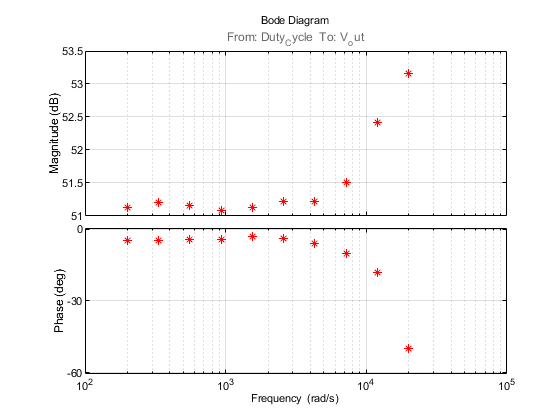


[sysData,simlog] = frestimate(mdl,ios,in);
bopt               = bodeoptions;
bopt.Grid          = 'on';
bopt.PhaseMatching = 'on';
figure, bode(sysData,'*r',bopt)


% load Transfer_Function_Measurement_data

sysA = tfest(sysData,2)


sysA =
 
  From input "Duty_Cycle" to output "V_out":
     3.69e06 s + 2.033e11
  ---------------------------
  s^2 + 2.217e04 s + 5.671e08
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                    
Estimated using TFEST on frequency response data "sysData".
Fit to estimation data: 83.65%                             
FPE: 617.8, MSE: 264.8                                     


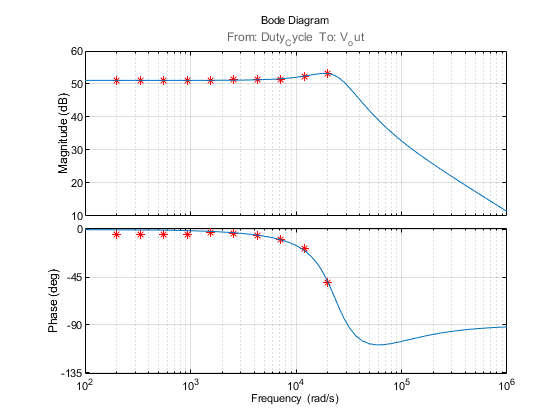

figure, bode(sysData,'r*',sysA,bopt)